# Load ROS_Bag

bag = rosbag('2024-03-22-06-26-38.bag');

# TF Data

states_message=select(bag,'MessageType','tf/tfMessage');
TF_data=readMessages(states_message);
TF_pose = zeros(7705,4);
j = 1;

for i = 1:7705
    if i == 1 
        TF_pose(j,1) = TF_data{i,1}.Transforms.Transform.Translation.X;
        TF_pose(j,2) = TF_data{i,1}.Transforms.Transform.Translation.Y;
    
        Z = TF_data{i,1}.Transforms.Transform.Rotation.Z
        W = TF_data{i,1}.Transforms.Transform.Rotation.W
        theta = atan(2*W*Z/(1-2*Z*Z))
        TF_pose(j,3) = theta
        TF_pose(j,4) = TF_data{i,1}.Transforms.Header.Stamp.Sec
        j = j + 1
        continue
    end
        
    if TF_data{i,1}.Transforms.Header.Stamp.Sec ~= TF_data{i-1,1}.Transforms.Header.Stamp.Sec 
        TF_pose(j,1) = TF_data{i,1}.Transforms.Transform.Translation.X;
        TF_pose(j,2) = TF_data{i,1}.Transforms.Transform.Translation.Y;
    
        Z = TF_data{i,1}.Transforms.Transform.Rotation.Z
        W = TF_data{i,1}.Transforms.Transform.Rotation.W
        theta = atan(2*W*Z/(1-2*Z*Z))
        TF_pose(j,3) = theta
        TF_pose(j,4) = TF_data{i,1}.Transforms.Header.Stamp.Sec
        j = j+1
    else
        continue
    end
     
end

Z = 0.0046

W = 1.0000

theta = 0.0093

TF_pose =     0.0000   -0.0000    0.0093         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


j = 2

Z = 0.0047

W = 1.0000

theta = 0.0095

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


j = 3

Z = 0.0051

W = 1.0000

theta = 0.0101

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


j = 4

Z = 0.0052

W = 1.0000

theta = 0.0104

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


j = 5

Z = 0.0055

W = 1.0000

theta = 0.0111

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


j = 6

Z = 0.0059

W = 1.0000

theta = 0.0119

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


j = 7

Z = 0.0063

W = 1.0000

theta = 0.0127

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
         0         0         0         0
         0         0         0         0
         0         0         0         0


j = 8

Z = 0.0066

W = 1.0000

theta = 0.0132

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000         0
         0         0         0         0
         0         0         0         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
         0         0         0         0
         0         0         0         0


j = 9

Z = 0.0069

W = 1.0000

theta = 0.0139

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000         0
         0         0         0         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
         0         0         0         0


j = 10

Z = 0.0081

W = 1.0000

theta = 0.0163

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000         0


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 11

Z = 0.0094

W = 1.0000

theta = 0.0188

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 12

Z = 0.0125

W = 0.9999

theta = 0.0250

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 13

Z = 0.0101

W = 0.9999

theta = 0.0202

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 14

Z = 0.0114

W = 0.9999

theta = 0.0229

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 15

Z = 0.0132

W = 0.9999

theta = 0.0264

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 16

Z = 0.0149

W = 0.9999

theta = 0.0298

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 17

Z = 0.0149

W = 0.9999

theta = 0.0298

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 18

Z = 0.0176

W = 0.9998

theta = 0.0353

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 19

Z = 0.0198

W = 0.9998

theta = 0.0395

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 20

Z = 0.0191

W = 0.9998

theta = 0.0382

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 21

Z = 0.0205

W = 0.9998

theta = 0.0409

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 22

Z = 0.0224

W = 0.9997

theta = 0.0448

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 23

Z = 0.0249

W = 0.9997

theta = 0.0497

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 24

Z = 0.0237

W = 0.9997

theta = 0.0475

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 25

Z = 0.0277

W = 0.9996

theta = 0.0554

TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 26

Z = 0.0292

W = 0.9996

theta = 0.0584

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 27

Z = 0.0291

W = 0.9996

theta = 0.0582

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 28

Z = 0.0291

W = 0.9996

theta = 0.0583

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 29

Z = 0.0327

W = 0.9995

theta = 0.0654

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 30

Z = 0.0342

W = 0.9994

theta = 0.0685

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 31

Z = 0.0334

W = 0.9994

theta = 0.0669

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 32

Z = 0.0368

W = 0.9993

theta = 0.0737

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 33

Z = 0.0392

W = 0.9992

theta = 0.0784

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 34

Z = 0.0394

W = 0.9992

theta = 0.0789

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 35

Z = 0.0388

W = 0.9992

theta = 0.0776

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 36

Z = 0.0238

W = 0.9997

theta = 0.0476

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 37

Z = -0.0687

W = 0.9976

theta = -0.1375

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 38

Z = -0.1637

W = 0.9865

theta = -0.3288

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 39

Z = -0.2530

W = 0.9675

theta = -0.5116

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 40

Z = -0.3093

W = 0.9510

theta = -0.6288

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 41

Z = -0.3179

W = 0.9481

theta = -0.6471

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 42

Z = -0.3185

W = 0.9479

theta = -0.6482

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 43

Z = -0.3131

W = 0.9497

theta = -0.6369

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 44

Z = -0.3398

W = 0.9405

theta = -0.6933

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 45

Z = -0.3705

W = 0.9288

theta = -0.7591

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 46

Z = -0.3685

W = 0.9296

theta = -0.7548

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 47

Z = -0.3833

W = 0.9236

theta = -0.7868

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 48

Z = -0.4134

W = 0.9106

theta = -0.8523

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 49

Z = -0.4130

W = 0.9107

theta = -0.8515

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 50

Z = -0.4113

W = 0.9115

theta = -0.8478

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 51

Z = -0.4080

W = 0.9130

theta = -0.8405

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 52

Z = -0.4077

W = 0.9131

theta = -0.8400

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 53

Z = -0.4057

W = 0.9140

theta = -0.8355

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 54

Z = -0.4042

W = 0.9147

theta = -0.8323

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 55

Z = -0.4041

W = 0.9147

theta = -0.8320

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 56

Z = -0.4040

W = 0.9147

theta = -0.8319

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 57

Z = -0.4039

W = 0.9148

theta = -0.8316

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 58

Z = -0.4018

W = 0.9157

theta = -0.8270

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 59

Z = -0.4017

W = 0.9158

theta = -0.8268

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 60

Z = -0.4017

W = 0.9158

theta = -0.8268

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 61

Z = -0.4016

W = 0.9158

theta = -0.8266

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 62

Z = -0.4006

W = 0.9162

theta = -0.8244

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 63

Z = -0.3988

W = 0.9170

theta = -0.8204

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 64

Z = -0.3984

W = 0.9172

theta = -0.8196

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 65

Z = -0.3971

W = 0.9178

theta = -0.8167

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 66

Z = -0.3973

W = 0.9177

theta = -0.8172

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 67

Z = -0.3974

W = 0.9177

theta = -0.8173

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 68

Z = -0.3972

W = 0.9177

theta = -0.8168

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 69

Z = -0.3977

W = 0.9175

theta = -0.8181

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 70

Z = -0.3955

W = 0.9184

theta = -0.8133

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 71

Z = -0.3973

W = 0.9177

theta = -0.8171

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 72

Z = -0.3963

W = 0.9181

theta = -0.8149

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 73

Z = -0.3964

W = 0.9181

theta = -0.8152

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 74

Z = -0.3958

W = 0.9183

theta = -0.8139

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 75

Z = -0.3941

W = 0.9191

theta = -0.8101

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 76

Z = -0.3792

W = 0.9253

theta = -0.7780

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 77

Z = -0.2863

W = 0.9582

theta = -0.5807

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 78

Z = -0.1953

W = 0.9807

theta = -0.3931

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 79

Z = -0.0971

W = 0.9953

theta = -0.1945

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 80

Z = -2.4211e-04

W = 1

theta = -4.8423e-04

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 81

Z = 0.0931

W = 0.9957

theta = 0.1865

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 82

Z = 0.1904

W = 0.9817

theta = 0.3832

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 83

Z = 0.2828

W = 0.9592

theta = 0.5733

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 84

Z = 0.3745

W = 0.9272

theta = 0.7676

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 85

Z = 0.4595

W = 0.8882

theta = 0.9550

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 86

Z = 0.5397

W = 0.8419

theta = 1.1401

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 87

Z = 0.6188

W = 0.7855

theta = 1.3345

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 88

Z = 0.6911

W = 0.7228

theta = 1.5260

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 89

Z = 0.7575

W = 0.6528

theta = -1.4226

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 90

Z = 0.8146

W = 0.5800

theta = -1.2375

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 91

Z = 0.8567

W = 0.5158

theta = -1.0840

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 92

Z = 0.8614

W = 0.5080

theta = -1.0657

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 93

Z = 0.8615

W = 0.5077

theta = -1.0650

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 94

Z = 0.8625

W = 0.5061

theta = -1.0613

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 95

Z = 0.8628

W = 0.5056

theta = -1.0602

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 96

Z = 0.8619

W = 0.5071

theta = -1.0637

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 97

Z = 0.8624

W = 0.5063

theta = -1.0617

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 98

Z = 0.8620

W = 0.5069

theta = -1.0631

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 99

Z = 0.8611

W = 0.5084

theta = -1.0666

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 100

Z = 0.8607

W = 0.5090

theta = -1.0682

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 101

Z = 0.8622

W = 0.5066

theta = -1.0625

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 102

Z = 0.8625

W = 0.5061

theta = -1.0613

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 103

Z = 0.8622

W = 0.5065

theta = -1.0622

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 104

Z = 0.8629

W = 0.5055

theta = -1.0598

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 105

Z = 0.8628

W = 0.5055

theta = -1.0599

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 106

Z = 0.8624

W = 0.5063

theta = -1.0617

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 107

Z = 0.8620

W = 0.5070

theta = -1.0634

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 108

Z = 0.8637

W = 0.5041

theta = -1.0566

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 109

Z = 0.8636

W = 0.5042

theta = -1.0569

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 110

Z = 0.8636

W = 0.5041

theta = -1.0568

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 111

Z = 0.8641

W = 0.5033

theta = -1.0548

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 112

Z = 0.8647

W = 0.5024

theta = -1.0527

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 113

Z = 0.8636

W = 0.5041

theta = -1.0568

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 114

Z = 0.8798

W = 0.4754

theta = -0.9908

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 115

Z = 0.9042

W = 0.4271

theta = -0.8825

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 116

Z = 0.9242

W = 0.3820

theta = -0.7839

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 117

Z = 0.9418

W = 0.3361

theta = -0.6856

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 118

Z = 0.9430

W = 0.3329

theta = -0.6787

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 119

Z = 0.9419

W = 0.3360

theta = -0.6853

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 120

Z = 0.9425

W = 0.3343

theta = -0.6816

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 121

Z = 0.9493

W = 0.3143

theta = -0.6394

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 122

Z = 0.9635

W = 0.2677

theta = -0.5421

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 123

Z = 0.9759

W = 0.2184

theta = -0.4404

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 124

Z = 0.9847

W = 0.1744

theta = -0.3506

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 125

Z = 0.9845

W = 0.1754

theta = -0.3526

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 126

Z = 0.9845

W = 0.1751

theta = -0.3521

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 127

Z = 0.9847

W = 0.1744

theta = -0.3505

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 128

Z = 0.9849

W = 0.1729

theta = -0.3475

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 129

Z = 0.9847

W = 0.1743

theta = -0.3503

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 130

Z = 0.9850

W = 0.1724

theta = -0.3465

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 131

Z = 0.9853

W = 0.1709

theta = -0.3435

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 132

Z = 0.9852

W = 0.1715

theta = -0.3448

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 133

Z = 0.9851

W = 0.1722

theta = -0.3461

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 134

Z = 0.9854

W = 0.1705

theta = -0.3426

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 135

Z = 0.9892

W = 0.1467

theta = -0.2945

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 136

Z = 0.9922

W = 0.1246

theta = -0.2499

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 137

Z = 0.9924

W = 0.1233

theta = -0.2471

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 138

Z = 0.9924

W = 0.1234

theta = -0.2474

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 139

Z = 0.9966

W = 0.0827

theta = -0.1655

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 140

Z = 0.9995

W = 0.0300

theta = -0.0600

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 141

Z = 0.9998

W = -0.0202

theta = 0.0404

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 142

Z = 0.9976

W = -0.0691

theta = 0.1382

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 143

Z = 0.9928

W = -0.1201

theta = 0.2408

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 144

Z = 0.9856

W = -0.1694

theta = 0.3404

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 145

Z = 0.9759

W = -0.2184

theta = 0.4403

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 146

Z = 0.9635

W = -0.2678

theta = 0.5422

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 147

Z = 0.9493

W = -0.3144

theta = 0.6396

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 148

Z = 0.9320

W = -0.3626

theta = 0.7421

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 149

Z = 0.9119

W = -0.4104

theta = 0.8458

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 150

Z = 0.8907

W = -0.4546

theta = 0.9438

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 151

Z = 0.8669

W = -0.4985

theta = 1.0437

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 152

Z = 0.8605

W = -0.5094

theta = 1.0689

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 153

Z = 0.8606

W = -0.5093

theta = 1.0688

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 154

Z = 0.8602

W = -0.5099

theta = 1.0702

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 155

Z = 0.8600

W = -0.5103

theta = 1.0710

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 156

Z = 0.8604

W = -0.5097

theta = 1.0696

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 157

Z = 0.8439

W = -0.5364

theta = 1.1324

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 158

Z = 0.8348

W = -0.5506

theta = 1.1661

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 159

Z = 0.8346

W = -0.5508

theta = 1.1667

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 160

Z = 0.8354

W = -0.5497

theta = 1.1640

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 161

Z = 0.8337

W = -0.5522

theta = 1.1701

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 162

Z = 0.8343

W = -0.5513

theta = 1.1679

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 163

Z = 0.8348

W = -0.5506

theta = 1.1662

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 164

Z = 0.8336

W = -0.5524

theta = 1.1704

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 165

Z = -0.8064

W = 0.5914

theta = 1.2657

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 166

Z = -0.8060

W = 0.5919

theta = 1.2669

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 167

Z = -0.8021

W = 0.5973

theta = 1.2801

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 168

Z = -0.7885

W = 0.6150

theta = 1.3249

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 169

Z = -0.7886

W = 0.6149

theta = 1.3246

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 170

Z = -0.7898

W = 0.6134

theta = 1.3206

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 171

Z = -0.7888

W = 0.6146

theta = 1.3237

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 172

Z = -0.7869

W = 0.6171

theta = 1.3301

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 173

Z = -0.7869

W = 0.6170

theta = 1.3300

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 174

Z = -0.7869

W = 0.6171

theta = 1.3301

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 175

Z = -0.7868

W = 0.6173

theta = 1.3305

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 176

Z = -0.7855

W = 0.6189

theta = 1.3346

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 177

Z = -0.7867

W = 0.6174

theta = 1.3308

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 178

Z = -0.7874

W = 0.6165

theta = 1.3285

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 179

Z = -0.7886

W = 0.6150

theta = 1.3247

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 180

Z = -0.7882

W = 0.6155

theta = 1.3260

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 181

Z = -0.7871

W = 0.6168

theta = 1.3294

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 182

Z = 0.8114

W = -0.5845

theta = 1.2486

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 183

Z = 0.8180

W = -0.5752

theta = 1.2258

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 184

Z = 0.8181

W = -0.5751

theta = 1.2255

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 185

Z = 0.8175

W = -0.5759

theta = 1.2273

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 186

Z = 0.8171

W = -0.5766

theta = 1.2290

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 187

Z = 0.8247

W = -0.5655

theta = 1.2021

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 188

Z = 0.8516

W = -0.5241

theta = 1.1034

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 189

Z = 0.8754

W = -0.4833

theta = 1.0089

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 190

Z = 0.8959

W = -0.4443

theta = 0.9208

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 191

Z = 0.9166

W = -0.3999

theta = 0.8227

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 192

Z = 0.9352

W = -0.3541

theta = 0.7240

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 193

Z = 0.9510

W = -0.3092

theta = 0.6286

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 194

Z = 0.9646

W = -0.2637

theta = 0.5338

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 195

Z = 0.9762

W = -0.2170

theta = 0.4374

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 196

Z = 0.9853

W = -0.1707

theta = 0.3430

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 197

Z = 0.9894

W = -0.1450

theta = 0.2911

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 198

Z = 0.9906

W = -0.1371

theta = 0.2751

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 199

Z = 0.9961

W = -0.0887

theta = 0.1777

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 200

Z = 0.9991

W = -0.0427

theta = 0.0854

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 201

Z = 1.0000

W = 0.0032

theta = -0.0065

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 202

Z = 0.9989

W = 0.0459

theta = -0.0918

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 203

Z = 0.9956

W = 0.0932

theta = -0.1867

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 204

Z = 0.9915

W = 0.1302

theta = -0.2611

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 205

Z = 0.9915

W = 0.1301

theta = -0.2609

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 206

Z = 0.9918

W = 0.1281

theta = -0.2569

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 207

Z = 0.9919

W = 0.1270

theta = -0.2547

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 208

Z = 0.9919

W = 0.1272

theta = -0.2550

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 209

Z = 0.9919

W = 0.1273

theta = -0.2553

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 210

Z = 0.9921

W = 0.1251

theta = -0.2509

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 211

Z = 0.9921

W = 0.1252

theta = -0.2511

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 212

Z = 0.9922

W = 0.1248

theta = -0.2502

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 213

Z = 0.9923

W = 0.1236

theta = -0.2478

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 214

Z = 0.9925

W = 0.1222

theta = -0.2451

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 215

Z = 0.9925

W = 0.1226

theta = -0.2458

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 216

Z = 0.9925

W = 0.1222

theta = -0.2451

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 217

Z = 0.9928

W = 0.1199

theta = -0.2403

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 218

Z = 0.9927

W = 0.1204

theta = -0.2413

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 219

Z = 0.9862

W = 0.1654

theta = -0.3322

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 220

Z = 0.9834

W = 0.1817

theta = -0.3655

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 221

Z = 0.9839

W = 0.1787

theta = -0.3594

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 222

Z = 0.9839

W = 0.1789

theta = -0.3597

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 223

Z = 0.9836

W = 0.1803

theta = -0.3627

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 224

Z = 0.9841

W = 0.1777

theta = -0.3573

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 225

Z = 0.9780

W = 0.2087

theta = -0.4205

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 226

Z = 0.9666

W = 0.2564

theta = -0.5186

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 227

Z = 0.9525

W = 0.3044

theta = -0.6187

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 228

Z = 0.9372

W = 0.3487

theta = -0.7124

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 229

Z = 0.9194

W = 0.3933

theta = -0.8084

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 230

Z = 0.8990

W = 0.4379

theta = -0.9064

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 231

Z = 0.8752

W = 0.4838

theta = -1.0100

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 232

Z = 0.8509

W = 0.5253

theta = -1.1062

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 233

Z = 0.8343

W = 0.5514

theta = -1.1680

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 234

Z = 0.8352

W = 0.5500

theta = -1.1647

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 235

Z = 0.8349

W = 0.5503

theta = -1.1656

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 236

Z = 0.8356

W = 0.5494

theta = -1.1633

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 237

Z = 0.8239

W = 0.5667

theta = -1.2051

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 238

Z = 0.7944

W = 0.6074

theta = -1.3054

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 239

Z = 0.7629

W = 0.6465

theta = -1.4060

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 240

Z = 0.7309

W = 0.6825

theta = -1.5024

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 241

Z = 0.7165

W = 0.6976

theta = -1.5441

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 242

Z = 0.7191

W = 0.6949

theta = -1.5366

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 243

Z = 0.7197

W = 0.6943

theta = -1.5349

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 244

Z = 0.7211

W = 0.6929

theta = -1.5309

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 245

Z = 0.7266

W = 0.6871

theta = -1.5149

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 246

Z = 0.7279

W = 0.6857

theta = -1.5111

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 247

Z = 0.7271

W = 0.6866

theta = -1.5135

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 248

Z = 0.7223

W = 0.6916

theta = -1.5273

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 249

Z = 0.7213

W = 0.6926

theta = -1.5301

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 250

Z = 0.7243

W = 0.6895

theta = -1.5215

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 251

Z = 0.7224

W = 0.6915

theta = -1.5270

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 252

Z = 0.7225

W = 0.6914

theta = -1.5267

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 253

Z = 0.7232

W = 0.6906

theta = -1.5248

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 254

Z = 0.7227

W = 0.6911

theta = -1.5261

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 255

Z = 0.7222

W = 0.6917

theta = -1.5276

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 256

Z = 0.7227

W = 0.6912

theta = -1.5262

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 257

Z = 0.7223

W = 0.6916

theta = -1.5274

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 258

Z = 0.7234

W = 0.6904

theta = -1.5241

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 259

Z = 0.7242

W = 0.6896

theta = -1.5220

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 260

Z = 0.7242

W = 0.6896

theta = -1.5220

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 261

Z = 0.7242

W = 0.6896

theta = -1.5219

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 262

Z = 0.7242

W = 0.6896

theta = -1.5218

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 263

Z = 0.7242

W = 0.6896

theta = -1.5218

TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


TF_pose = 7705×4
1.0e+09 *

    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000   -0.0000    0.0000    1.7111
    0.0000    0.0000    0.0000    1.7111


j = 264

visuala

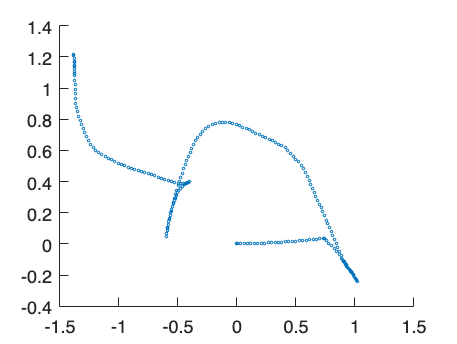

scatter(TF_pose(:,1),TF_pose(:,2),2);

## Laser Data

states_message=select(bag,'MessageType','sensor_msgs/LaserScan');
Laser_data=readMessages(states_message);


Laser = struct('t', 0, 'Ranges', zeros(236, 1), 'angle', zeros(236, 1));
initialValue = 0.0270;
step = 0.0265;
angle = initialValue + (0:235) * step;
j=1;

for i = 1:2510
    if i==1
        Laser(j).Ranges = Laser_data{i,1}.Ranges
        Laser(j).angle = angle
        Laser(j).t = Laser_data{i,1}.Header.Stamp.Sec
        j = j+1
        continue
    end

    if Laser_data{i,1}.Header.Stamp.Sec ~= Laser_data{i-1,1}.Header.Stamp.Sec
        Laser(j).Ranges = Laser_data{i,1}.Ranges
        Laser(j).angle = angle
        Laser(j).t = Laser_data{i,1}.Header.Stamp.Sec
        j = j+1
    else
        continue
    end
        
end

Laser = struct with fields:
         t: 0
    Ranges: [236×1 single]
     angle: [236×1 double]


Laser = struct with fields:
         t: 0
    Ranges: [236×1 single]
     angle: [0.0270 0.0535 0.0800 0.1065 0.1330 0.1595 0.1860 0.2125 0.2390 0.2655 0.2920 0.3185 0.3450 0.3715 0.3980 0.4245 0.4510 0.4775 0.5040 0.5305 0.5570 0.5835 0.6100 0.6365 0.6630 0.6895 0.7160 0.7425 0.7690 0.7955 0.8220 0.8485 … ] (1×236 double)


Laser = struct with fields:
         t: 1.7111e+09
    Ranges: [236×1 single]
     angle: [0.0270 0.0535 0.0800 0.1065 0.1330 0.1595 0.1860 0.2125 0.2390 0.2655 0.2920 0.3185 0.3450 0.3715 0.3980 0.4245 0.4510 0.4775 0.5040 0.5305 0.5570 0.5835 0.6100 0.6365 0.6630 0.6895 0.7160 0.7425 0.7690 0.7955 0.8220 0.8485 … ] (1×236 double)


j = 2

Laser = 1×2 struct array with fields:
    t
    Ranges
    angle


Laser = 1×2 struct array with fields:
    t
    Ranges
    angle


Laser = 1×2 struct array with fields:
    t
    Ranges
    angle


j = 3

Laser = 1×3 struct array with fields:
    t
    Ranges
    angle


Laser = 1×3 struct array with fields:
    t
    Ranges
    angle


Laser = 1×3 struct array with fields:
    t
    Ranges
    angle


j = 4

Laser = 1×4 struct array with fields:
    t
    Ranges
    angle


Laser = 1×4 struct array with fields:
    t
    Ranges
    angle


Laser = 1×4 struct array with fields:
    t
    Ranges
    angle


j = 5

Laser = 1×5 struct array with fields:
    t
    Ranges
    angle


Laser = 1×5 struct array with fields:
    t
    Ranges
    angle


Laser = 1×5 struct array with fields:
    t
    Ranges
    angle


j = 6

Laser = 1×6 struct array with fields:
    t
    Ranges
    angle


Laser = 1×6 struct array with fields:
    t
    Ranges
    angle


Laser = 1×6 struct array with fields:
    t
    Ranges
    angle


j = 7

Laser = 1×7 struct array with fields:
    t
    Ranges
    angle


Laser = 1×7 struct array with fields:
    t
    Ranges
    angle


Laser = 1×7 struct array with fields:
    t
    Ranges
    angle


j = 8

Laser = 1×8 struct array with fields:
    t
    Ranges
    angle


Laser = 1×8 struct array with fields:
    t
    Ranges
    angle


Laser = 1×8 struct array with fields:
    t
    Ranges
    angle


j = 9

Laser = 1×9 struct array with fields:
    t
    Ranges
    angle


Laser = 1×9 struct array with fields:
    t
    Ranges
    angle


Laser = 1×9 struct array with fields:
    t
    Ranges
    angle


j = 10

Laser = 1×10 struct array with fields:
    t
    Ranges
    angle


Laser = 1×10 struct array with fields:
    t
    Ranges
    angle


Laser = 1×10 struct array with fields:
    t
    Ranges
    angle


j = 11

Laser = 1×11 struct array with fields:
    t
    Ranges
    angle


Laser = 1×11 struct array with fields:
    t
    Ranges
    angle


Laser = 1×11 struct array with fields:
    t
    Ranges
    angle


j = 12

Laser = 1×12 struct array with fields:
    t
    Ranges
    angle


Laser = 1×12 struct array with fields:
    t
    Ranges
    angle


Laser = 1×12 struct array with fields:
    t
    Ranges
    angle


j = 13

Laser = 1×13 struct array with fields:
    t
    Ranges
    angle


Laser = 1×13 struct array with fields:
    t
    Ranges
    angle


Laser = 1×13 struct array with fields:
    t
    Ranges
    angle


j = 14

Laser = 1×14 struct array with fields:
    t
    Ranges
    angle


Laser = 1×14 struct array with fields:
    t
    Ranges
    angle


Laser = 1×14 struct array with fields:
    t
    Ranges
    angle


j = 15

Laser = 1×15 struct array with fields:
    t
    Ranges
    angle


Laser = 1×15 struct array with fields:
    t
    Ranges
    angle


Laser = 1×15 struct array with fields:
    t
    Ranges
    angle


j = 16

Laser = 1×16 struct array with fields:
    t
    Ranges
    angle


Laser = 1×16 struct array with fields:
    t
    Ranges
    angle


Laser = 1×16 struct array with fields:
    t
    Ranges
    angle


j = 17

Laser = 1×17 struct array with fields:
    t
    Ranges
    angle


Laser = 1×17 struct array with fields:
    t
    Ranges
    angle


Laser = 1×17 struct array with fields:
    t
    Ranges
    angle


j = 18

Laser = 1×18 struct array with fields:
    t
    Ranges
    angle


Laser = 1×18 struct array with fields:
    t
    Ranges
    angle


Laser = 1×18 struct array with fields:
    t
    Ranges
    angle


j = 19

Laser = 1×19 struct array with fields:
    t
    Ranges
    angle


Laser = 1×19 struct array with fields:
    t
    Ranges
    angle


Laser = 1×19 struct array with fields:
    t
    Ranges
    angle


j = 20

Laser = 1×20 struct array with fields:
    t
    Ranges
    angle


Laser = 1×20 struct array with fields:
    t
    Ranges
    angle


Laser = 1×20 struct array with fields:
    t
    Ranges
    angle


j = 21

Laser = 1×21 struct array with fields:
    t
    Ranges
    angle


Laser = 1×21 struct array with fields:
    t
    Ranges
    angle


Laser = 1×21 struct array with fields:
    t
    Ranges
    angle


j = 22

Laser = 1×22 struct array with fields:
    t
    Ranges
    angle


Laser = 1×22 struct array with fields:
    t
    Ranges
    angle


Laser = 1×22 struct array with fields:
    t
    Ranges
    angle


j = 23

Laser = 1×23 struct array with fields:
    t
    Ranges
    angle


Laser = 1×23 struct array with fields:
    t
    Ranges
    angle


Laser = 1×23 struct array with fields:
    t
    Ranges
    angle


j = 24

Laser = 1×24 struct array with fields:
    t
    Ranges
    angle


Laser = 1×24 struct array with fields:
    t
    Ranges
    angle


Laser = 1×24 struct array with fields:
    t
    Ranges
    angle


j = 25

Laser = 1×25 struct array with fields:
    t
    Ranges
    angle


Laser = 1×25 struct array with fields:
    t
    Ranges
    angle


Laser = 1×25 struct array with fields:
    t
    Ranges
    angle


j = 26

Laser = 1×26 struct array with fields:
    t
    Ranges
    angle


Laser = 1×26 struct array with fields:
    t
    Ranges
    angle


Laser = 1×26 struct array with fields:
    t
    Ranges
    angle


j = 27

Laser = 1×27 struct array with fields:
    t
    Ranges
    angle


Laser = 1×27 struct array with fields:
    t
    Ranges
    angle


Laser = 1×27 struct array with fields:
    t
    Ranges
    angle


j = 28

Laser = 1×28 struct array with fields:
    t
    Ranges
    angle


Laser = 1×28 struct array with fields:
    t
    Ranges
    angle


Laser = 1×28 struct array with fields:
    t
    Ranges
    angle


j = 29

Laser = 1×29 struct array with fields:
    t
    Ranges
    angle


Laser = 1×29 struct array with fields:
    t
    Ranges
    angle


Laser = 1×29 struct array with fields:
    t
    Ranges
    angle


j = 30

Laser = 1×30 struct array with fields:
    t
    Ranges
    angle


Laser = 1×30 struct array with fields:
    t
    Ranges
    angle


Laser = 1×30 struct array with fields:
    t
    Ranges
    angle


j = 31

Laser = 1×31 struct array with fields:
    t
    Ranges
    angle


Laser = 1×31 struct array with fields:
    t
    Ranges
    angle


Laser = 1×31 struct array with fields:
    t
    Ranges
    angle


j = 32

Laser = 1×32 struct array with fields:
    t
    Ranges
    angle


Laser = 1×32 struct array with fields:
    t
    Ranges
    angle


Laser = 1×32 struct array with fields:
    t
    Ranges
    angle


j = 33

Laser = 1×33 struct array with fields:
    t
    Ranges
    angle


Laser = 1×33 struct array with fields:
    t
    Ranges
    angle


Laser = 1×33 struct array with fields:
    t
    Ranges
    angle


j = 34

Laser = 1×34 struct array with fields:
    t
    Ranges
    angle


Laser = 1×34 struct array with fields:
    t
    Ranges
    angle


Laser = 1×34 struct array with fields:
    t
    Ranges
    angle


j = 35

Laser = 1×35 struct array with fields:
    t
    Ranges
    angle


Laser = 1×35 struct array with fields:
    t
    Ranges
    angle


Laser = 1×35 struct array with fields:
    t
    Ranges
    angle


j = 36

Laser = 1×36 struct array with fields:
    t
    Ranges
    angle


Laser = 1×36 struct array with fields:
    t
    Ranges
    angle


Laser = 1×36 struct array with fields:
    t
    Ranges
    angle


j = 37

Laser = 1×37 struct array with fields:
    t
    Ranges
    angle


Laser = 1×37 struct array with fields:
    t
    Ranges
    angle


Laser = 1×37 struct array with fields:
    t
    Ranges
    angle


j = 38

Laser = 1×38 struct array with fields:
    t
    Ranges
    angle


Laser = 1×38 struct array with fields:
    t
    Ranges
    angle


Laser = 1×38 struct array with fields:
    t
    Ranges
    angle


j = 39

Laser = 1×39 struct array with fields:
    t
    Ranges
    angle


Laser = 1×39 struct array with fields:
    t
    Ranges
    angle


Laser = 1×39 struct array with fields:
    t
    Ranges
    angle


j = 40

Laser = 1×40 struct array with fields:
    t
    Ranges
    angle


Laser = 1×40 struct array with fields:
    t
    Ranges
    angle


Laser = 1×40 struct array with fields:
    t
    Ranges
    angle


j = 41

Laser = 1×41 struct array with fields:
    t
    Ranges
    angle


Laser = 1×41 struct array with fields:
    t
    Ranges
    angle


Laser = 1×41 struct array with fields:
    t
    Ranges
    angle


j = 42

Laser = 1×42 struct array with fields:
    t
    Ranges
    angle


Laser = 1×42 struct array with fields:
    t
    Ranges
    angle


Laser = 1×42 struct array with fields:
    t
    Ranges
    angle


j = 43

Laser = 1×43 struct array with fields:
    t
    Ranges
    angle


Laser = 1×43 struct array with fields:
    t
    Ranges
    angle


Laser = 1×43 struct array with fields:
    t
    Ranges
    angle


j = 44

Laser = 1×44 struct array with fields:
    t
    Ranges
    angle


Laser = 1×44 struct array with fields:
    t
    Ranges
    angle


Laser = 1×44 struct array with fields:
    t
    Ranges
    angle


j = 45

Laser = 1×45 struct array with fields:
    t
    Ranges
    angle


Laser = 1×45 struct array with fields:
    t
    Ranges
    angle


Laser = 1×45 struct array with fields:
    t
    Ranges
    angle


j = 46

Laser = 1×46 struct array with fields:
    t
    Ranges
    angle


Laser = 1×46 struct array with fields:
    t
    Ranges
    angle


Laser = 1×46 struct array with fields:
    t
    Ranges
    angle


j = 47

Laser = 1×47 struct array with fields:
    t
    Ranges
    angle


Laser = 1×47 struct array with fields:
    t
    Ranges
    angle


Laser = 1×47 struct array with fields:
    t
    Ranges
    angle


j = 48

Laser = 1×48 struct array with fields:
    t
    Ranges
    angle


Laser = 1×48 struct array with fields:
    t
    Ranges
    angle


Laser = 1×48 struct array with fields:
    t
    Ranges
    angle


j = 49

Laser = 1×49 struct array with fields:
    t
    Ranges
    angle


Laser = 1×49 struct array with fields:
    t
    Ranges
    angle


Laser = 1×49 struct array with fields:
    t
    Ranges
    angle


j = 50

Laser = 1×50 struct array with fields:
    t
    Ranges
    angle


Laser = 1×50 struct array with fields:
    t
    Ranges
    angle


Laser = 1×50 struct array with fields:
    t
    Ranges
    angle


j = 51

Laser = 1×51 struct array with fields:
    t
    Ranges
    angle


Laser = 1×51 struct array with fields:
    t
    Ranges
    angle


Laser = 1×51 struct array with fields:
    t
    Ranges
    angle


j = 52

Laser = 1×52 struct array with fields:
    t
    Ranges
    angle


Laser = 1×52 struct array with fields:
    t
    Ranges
    angle


Laser = 1×52 struct array with fields:
    t
    Ranges
    angle


j = 53

Laser = 1×53 struct array with fields:
    t
    Ranges
    angle


Laser = 1×53 struct array with fields:
    t
    Ranges
    angle


Laser = 1×53 struct array with fields:
    t
    Ranges
    angle


j = 54

Laser = 1×54 struct array with fields:
    t
    Ranges
    angle


Laser = 1×54 struct array with fields:
    t
    Ranges
    angle


Laser = 1×54 struct array with fields:
    t
    Ranges
    angle


j = 55

Laser = 1×55 struct array with fields:
    t
    Ranges
    angle


Laser = 1×55 struct array with fields:
    t
    Ranges
    angle


Laser = 1×55 struct array with fields:
    t
    Ranges
    angle


j = 56

Laser = 1×56 struct array with fields:
    t
    Ranges
    angle


Laser = 1×56 struct array with fields:
    t
    Ranges
    angle


Laser = 1×56 struct array with fields:
    t
    Ranges
    angle


j = 57

Laser = 1×57 struct array with fields:
    t
    Ranges
    angle


Laser = 1×57 struct array with fields:
    t
    Ranges
    angle


Laser = 1×57 struct array with fields:
    t
    Ranges
    angle


j = 58

Laser = 1×58 struct array with fields:
    t
    Ranges
    angle


Laser = 1×58 struct array with fields:
    t
    Ranges
    angle


Laser = 1×58 struct array with fields:
    t
    Ranges
    angle


j = 59

Laser = 1×59 struct array with fields:
    t
    Ranges
    angle


Laser = 1×59 struct array with fields:
    t
    Ranges
    angle


Laser = 1×59 struct array with fields:
    t
    Ranges
    angle


j = 60

Laser = 1×60 struct array with fields:
    t
    Ranges
    angle


Laser = 1×60 struct array with fields:
    t
    Ranges
    angle


Laser = 1×60 struct array with fields:
    t
    Ranges
    angle


j = 61

Laser = 1×61 struct array with fields:
    t
    Ranges
    angle


Laser = 1×61 struct array with fields:
    t
    Ranges
    angle


Laser = 1×61 struct array with fields:
    t
    Ranges
    angle


j = 62

Laser = 1×62 struct array with fields:
    t
    Ranges
    angle


Laser = 1×62 struct array with fields:
    t
    Ranges
    angle


Laser = 1×62 struct array with fields:
    t
    Ranges
    angle


j = 63

Laser = 1×63 struct array with fields:
    t
    Ranges
    angle


Laser = 1×63 struct array with fields:
    t
    Ranges
    angle


Laser = 1×63 struct array with fields:
    t
    Ranges
    angle


j = 64

Laser = 1×64 struct array with fields:
    t
    Ranges
    angle


Laser = 1×64 struct array with fields:
    t
    Ranges
    angle


Laser = 1×64 struct array with fields:
    t
    Ranges
    angle


j = 65

Laser = 1×65 struct array with fields:
    t
    Ranges
    angle


Laser = 1×65 struct array with fields:
    t
    Ranges
    angle


Laser = 1×65 struct array with fields:
    t
    Ranges
    angle


j = 66

Laser = 1×66 struct array with fields:
    t
    Ranges
    angle


Laser = 1×66 struct array with fields:
    t
    Ranges
    angle


Laser = 1×66 struct array with fields:
    t
    Ranges
    angle


j = 67

Laser = 1×67 struct array with fields:
    t
    Ranges
    angle


Laser = 1×67 struct array with fields:
    t
    Ranges
    angle


Laser = 1×67 struct array with fields:
    t
    Ranges
    angle


j = 68

Laser = 1×68 struct array with fields:
    t
    Ranges
    angle


Laser = 1×68 struct array with fields:
    t
    Ranges
    angle


Laser = 1×68 struct array with fields:
    t
    Ranges
    angle


j = 69

Laser = 1×69 struct array with fields:
    t
    Ranges
    angle


Laser = 1×69 struct array with fields:
    t
    Ranges
    angle


Laser = 1×69 struct array with fields:
    t
    Ranges
    angle


j = 70

Laser = 1×70 struct array with fields:
    t
    Ranges
    angle


Laser = 1×70 struct array with fields:
    t
    Ranges
    angle


Laser = 1×70 struct array with fields:
    t
    Ranges
    angle


j = 71

Laser = 1×71 struct array with fields:
    t
    Ranges
    angle


Laser = 1×71 struct array with fields:
    t
    Ranges
    angle


Laser = 1×71 struct array with fields:
    t
    Ranges
    angle


j = 72

Laser = 1×72 struct array with fields:
    t
    Ranges
    angle


Laser = 1×72 struct array with fields:
    t
    Ranges
    angle


Laser = 1×72 struct array with fields:
    t
    Ranges
    angle


j = 73

Laser = 1×73 struct array with fields:
    t
    Ranges
    angle


Laser = 1×73 struct array with fields:
    t
    Ranges
    angle


Laser = 1×73 struct array with fields:
    t
    Ranges
    angle


j = 74

Laser = 1×74 struct array with fields:
    t
    Ranges
    angle


Laser = 1×74 struct array with fields:
    t
    Ranges
    angle


Laser = 1×74 struct array with fields:
    t
    Ranges
    angle


j = 75

Laser = 1×75 struct array with fields:
    t
    Ranges
    angle


Laser = 1×75 struct array with fields:
    t
    Ranges
    angle


Laser = 1×75 struct array with fields:
    t
    Ranges
    angle


j = 76

Laser = 1×76 struct array with fields:
    t
    Ranges
    angle


Laser = 1×76 struct array with fields:
    t
    Ranges
    angle


Laser = 1×76 struct array with fields:
    t
    Ranges
    angle


j = 77

Laser = 1×77 struct array with fields:
    t
    Ranges
    angle


Laser = 1×77 struct array with fields:
    t
    Ranges
    angle


Laser = 1×77 struct array with fields:
    t
    Ranges
    angle


j = 78

Laser = 1×78 struct array with fields:
    t
    Ranges
    angle


Laser = 1×78 struct array with fields:
    t
    Ranges
    angle


Laser = 1×78 struct array with fields:
    t
    Ranges
    angle


j = 79

Laser = 1×79 struct array with fields:
    t
    Ranges
    angle


Laser = 1×79 struct array with fields:
    t
    Ranges
    angle


Laser = 1×79 struct array with fields:
    t
    Ranges
    angle


j = 80

Laser = 1×80 struct array with fields:
    t
    Ranges
    angle


Laser = 1×80 struct array with fields:
    t
    Ranges
    angle


Laser = 1×80 struct array with fields:
    t
    Ranges
    angle


j = 81

Laser = 1×81 struct array with fields:
    t
    Ranges
    angle


Laser = 1×81 struct array with fields:
    t
    Ranges
    angle


Laser = 1×81 struct array with fields:
    t
    Ranges
    angle


j = 82

Laser = 1×82 struct array with fields:
    t
    Ranges
    angle


Laser = 1×82 struct array with fields:
    t
    Ranges
    angle


Laser = 1×82 struct array with fields:
    t
    Ranges
    angle


j = 83

Laser = 1×83 struct array with fields:
    t
    Ranges
    angle


Laser = 1×83 struct array with fields:
    t
    Ranges
    angle


Laser = 1×83 struct array with fields:
    t
    Ranges
    angle


j = 84

Laser = 1×84 struct array with fields:
    t
    Ranges
    angle


Laser = 1×84 struct array with fields:
    t
    Ranges
    angle


Laser = 1×84 struct array with fields:
    t
    Ranges
    angle


j = 85

Laser = 1×85 struct array with fields:
    t
    Ranges
    angle


Laser = 1×85 struct array with fields:
    t
    Ranges
    angle


Laser = 1×85 struct array with fields:
    t
    Ranges
    angle


j = 86

Laser = 1×86 struct array with fields:
    t
    Ranges
    angle


Laser = 1×86 struct array with fields:
    t
    Ranges
    angle


Laser = 1×86 struct array with fields:
    t
    Ranges
    angle


j = 87

Laser = 1×87 struct array with fields:
    t
    Ranges
    angle


Laser = 1×87 struct array with fields:
    t
    Ranges
    angle


Laser = 1×87 struct array with fields:
    t
    Ranges
    angle


j = 88

Laser = 1×88 struct array with fields:
    t
    Ranges
    angle


Laser = 1×88 struct array with fields:
    t
    Ranges
    angle


Laser = 1×88 struct array with fields:
    t
    Ranges
    angle


j = 89

Laser = 1×89 struct array with fields:
    t
    Ranges
    angle


Laser = 1×89 struct array with fields:
    t
    Ranges
    angle


Laser = 1×89 struct array with fields:
    t
    Ranges
    angle


j = 90

Laser = 1×90 struct array with fields:
    t
    Ranges
    angle


Laser = 1×90 struct array with fields:
    t
    Ranges
    angle


Laser = 1×90 struct array with fields:
    t
    Ranges
    angle


j = 91

Laser = 1×91 struct array with fields:
    t
    Ranges
    angle


Laser = 1×91 struct array with fields:
    t
    Ranges
    angle


Laser = 1×91 struct array with fields:
    t
    Ranges
    angle


j = 92

Laser = 1×92 struct array with fields:
    t
    Ranges
    angle


Laser = 1×92 struct array with fields:
    t
    Ranges
    angle


Laser = 1×92 struct array with fields:
    t
    Ranges
    angle


j = 93

Laser = 1×93 struct array with fields:
    t
    Ranges
    angle


Laser = 1×93 struct array with fields:
    t
    Ranges
    angle


Laser = 1×93 struct array with fields:
    t
    Ranges
    angle


j = 94

Laser = 1×94 struct array with fields:
    t
    Ranges
    angle


Laser = 1×94 struct array with fields:
    t
    Ranges
    angle


Laser = 1×94 struct array with fields:
    t
    Ranges
    angle


j = 95

Laser = 1×95 struct array with fields:
    t
    Ranges
    angle


Laser = 1×95 struct array with fields:
    t
    Ranges
    angle


Laser = 1×95 struct array with fields:
    t
    Ranges
    angle


j = 96

Laser = 1×96 struct array with fields:
    t
    Ranges
    angle


Laser = 1×96 struct array with fields:
    t
    Ranges
    angle


Laser = 1×96 struct array with fields:
    t
    Ranges
    angle


j = 97

Laser = 1×97 struct array with fields:
    t
    Ranges
    angle


Laser = 1×97 struct array with fields:
    t
    Ranges
    angle


Laser = 1×97 struct array with fields:
    t
    Ranges
    angle


j = 98

Laser = 1×98 struct array with fields:
    t
    Ranges
    angle


Laser = 1×98 struct array with fields:
    t
    Ranges
    angle


Laser = 1×98 struct array with fields:
    t
    Ranges
    angle


j = 99

Laser = 1×99 struct array with fields:
    t
    Ranges
    angle


Laser = 1×99 struct array with fields:
    t
    Ranges
    angle


Laser = 1×99 struct array with fields:
    t
    Ranges
    angle


j = 100

Laser = 1×100 struct array with fields:
    t
    Ranges
    angle


Laser = 1×100 struct array with fields:
    t
    Ranges
    angle


Laser = 1×100 struct array with fields:
    t
    Ranges
    angle


j = 101

Laser = 1×101 struct array with fields:
    t
    Ranges
    angle


Laser = 1×101 struct array with fields:
    t
    Ranges
    angle


Laser = 1×101 struct array with fields:
    t
    Ranges
    angle


j = 102

Laser = 1×102 struct array with fields:
    t
    Ranges
    angle


Laser = 1×102 struct array with fields:
    t
    Ranges
    angle


Laser = 1×102 struct array with fields:
    t
    Ranges
    angle


j = 103

Laser = 1×103 struct array with fields:
    t
    Ranges
    angle


Laser = 1×103 struct array with fields:
    t
    Ranges
    angle


Laser = 1×103 struct array with fields:
    t
    Ranges
    angle


j = 104

Laser = 1×104 struct array with fields:
    t
    Ranges
    angle


Laser = 1×104 struct array with fields:
    t
    Ranges
    angle


Laser = 1×104 struct array with fields:
    t
    Ranges
    angle


j = 105

Laser = 1×105 struct array with fields:
    t
    Ranges
    angle


Laser = 1×105 struct array with fields:
    t
    Ranges
    angle


Laser = 1×105 struct array with fields:
    t
    Ranges
    angle


j = 106

Laser = 1×106 struct array with fields:
    t
    Ranges
    angle


## Robot Data (Merge TF&Laser)


Robot_data = struct('t',0, 'pose',zeros(3,1), 'Ranges', zeros(236, 1), 'angle', zeros(236, 1));

for i = 1:length(TF_pose)
    t = TF_pose(i, 4);  
    
    
    matchIndex = find([Laser.t] == t);
    
    if ~isempty(matchIndex)
       
        Robot_data(end + 1).t = t;
        Robot_data(end).Ranges = Laser(matchIndex).Ranges;
        Robot_data(end).angle = Laser(matchIndex).angle;
        Robot_data(end).pose = TF_pose(i,1:3);

    end
end
